# Predict cancer metabolism from histone markers

**Author**: Scott Campit

## Summary

This notebook trains regressors on global chromatin profiles from the Cancer Cell Line Encylopedia to predict metabolite and metabolite ratio levels. Other validation sets are also used from the trained CCLE models.

## Data Preprocessing

clear all; 

GCPFilePath = '~/Data/Proteomics/CCLE/CCLE Global Chromatin Profiles.xlsx';
GCPSheet    = 'ACME'; 
GCP = readcell(GCPFilePath, ...
                "FileType", "spreadsheet", ...
                "Sheet", GCPSheet);
            
MetFilePath = '~/Data/Metabolomics/CCLE/ACME.csv';
MET = readcell(MetFilePath);
MET(:, 1) = [];

### Mapping data

First get chromatin markers and metabolite identifiers.

% IDs
chromatin_markers = string(GCP(1, 2:end));
metabolites       = string(MET(1, 2:end));

Next, get the intersection between both datasets based on cancer cell lines.

% Map data based on intersection
[~, ia, ib] = intersect(string(GCP(:, 1)), string(MET(:, 1)));
GCP = GCP(ia, :);
MET = MET(ib, :);

Finally, remove string identifiers from the dataset.

% Remove cell line identifiers
GCP(:, 1)  = [];
MET(:, 1) = [];

Convert all data to the same datatype double.

% GCP datasets
GCP = string(GCP);
GCP = str2double(GCP);

% Metabolomics datasets
MET = string(MET);
MET = str2double(MET);

Ensure the distributions are about Gaussian.

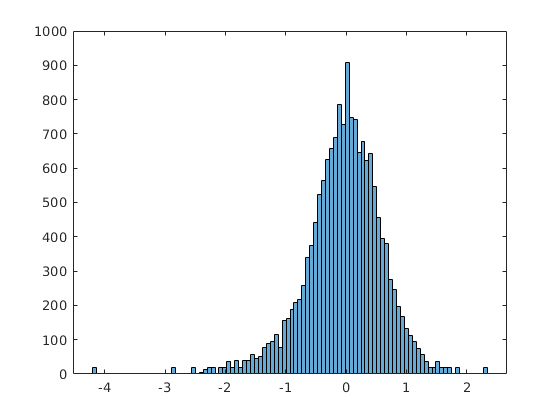

GCP_norm = quantilenorm(GCP);
histogram(quantilenorm(GCP), 100);

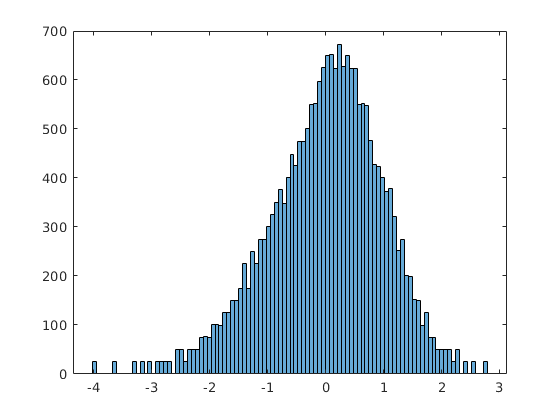

MET_norm = quantilenorm(zscore(MET));
histogram(quantilenorm(zscore(MET)), 100);

### Split data into a training and test set

First, let's split the data into a training and validation set.

% Set the training size and the random number generator for the
% trainTestSplit function.
GCP_norm(isnan(GCP_norm)) = 0;
MET_norm(isnan(MET_norm)) = 0; 
trainingSize = 0.7;
randomState = 'default';
data = trainTestSplit(GCP_norm, MET_norm, ...
                      trainingSize, ...
                      randomState);

## Predicting metabolism from GCP with hyperparameter optimization and K-fold cross validation

Next, let's perform some hyperparameter optimzation for the regressors using the training set. Note that `regressorEnsemble` is a custom function that performs hyperparameter optimization for the following models:

- Robust regression* - if the data supports ROLS

- Ridge regression

- LASSO

- Decision trees

- Least-squares boosting 

- Random forest

Hyperparameter optimization was performed using the `regressorEnsemble.mlx` function, which trains several regression models using k-fold cross validation. The code for this script can be found [here](https://github.com/ScottCampit/ml/blob/master/MATLAB/src/Ensemble/regressorEnsemble.mlx).

Note that the `regressorEnsemble.mlx` function automatically saves the intermediate models, as well as the final models selected from k-fold cross validation. 

% Train several regressor models to predict individual metabolites
%parpool(4);
savepath = '~/Data/Models/GCP to Met/';
kfold = 5

kfold = 5

best_mdls = regressorEnsemble(data.Xtrain, data.Ytrain, kfold, savepath);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


Error using save
Unable to write file /home/scampit/Data/Models/GCP to Met/model.mat: No such file or directory.

Error in regressorEnsemble (line 76)
            save(strcat(path, "model.mat"), ...

## Predicting GCP from metabolism with hyperparameter optimization and K-fold cross validation

This next section runs two sets of models: one set of models aims to predict [metabolomics <- epigenomics], while the other set of modesl aims to predict [epigenomics <- metabolomics].

clear data best_mdls;

% Set the training size and the random number generator for the
% trainTestSplit function.
data = trainTestSplit(MET, GCP, ...
                      trainingSize, ...
                      randomState);

%parpool(4);
savepath = '~/Data/Models/Met to GCP/';
best_mdls = regressorEnsemble(data.Xtrain, data.Ytrain, kfold, savepath);  